# **Cuantificación de una señal**

Generación de señal análoga

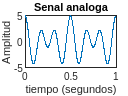

t=0:0.001:1;
f1=4; % Hz
f2=6; % Hz
xt=2*cos(2*pi*f1*t)+3*cos(2*pi*f2*t);
figure
plot(t,xt)
xlabel('tiempo (segundos)')
ylabel('Amplitud')
title('Senal analoga')

Discretización de la señal análoga, periodo de muestreo 1/24 de segundo

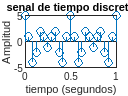

Ts=1/24;
Fs=1/Ts;
nTs=0:Ts:1;
xnTs=2*cos(2*pi*f1*nTs)+3*cos(2*pi*f2*nTs);
figure
stem(nTs,xnTs)
xlabel('tiempo (segundos)')
ylabel('Amplitud')
title('senal de tiempo discreto')

Señal análoga y discretizada superpuestas

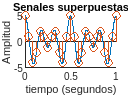

figure
hold on
plot(t,xt)
stem(nTs,xnTs)
xlabel('tiempo (segundos)')
ylabel('Amplitud')
title('Senales superpuestas')
hold off

Cuantificación de la señal:

- se define el rango de la señal (valores máxmio y mínimo)

- se define el número de bits para cuantificar (resolución)

- se determina el número de niveles de cuatificación

- se determina la altura del escalón de cuantificaión

ran=max(xt)-min(xt);%rango de la señal
nbits=8;% numero bits de cuantificacion
nnivs=(2^nbits)-1;%numero de niveles de cuantificacion
delta=ran/nnivs;%altura de nivel de cuantificacion

Con los datos anteriores se procede a calcular los valores de cada escalon de cuantificación

nive=min(xt):delta:max(xt);

Se calcula el valor que está en medio de cada escalón de cuantificación, esto se hace para realizar el cálculo de la cuantificación por redondeo

nivem=nive+delta/2;

Cuantificacón de la señal teniendo en cuenta los niveles calculados; los valores cuantificados quedan guardados en el arreglo xnq

El ciclo for realizará el cálculo  por cada muestra de la señal

El ciclo while busca el nivel de cuantificación correspondiente

[~,N]=size(nTs); % instantes de muestreo
xnq=zeros(1,N); % arreglo con ceros
for i=1:N
    j=1;
    while xnTs(i)>nivem(j)
        j=j+1;
    end
    xnq(i)=nive(j);
end

Gráfica de las señales con cuantificar y cuantificada. Las gráficas están superpuestas y no es apreciable la diferencia. Al disminuir el número de bits (nbits) se podrá notar la diferencia.

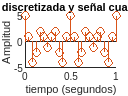

figure()
hold on
title('Señal discretizada y señal cuantificada')
stem(nTs,xnq) % señal cuantificada
stem(nTs,xnTs) % señal sin cuantificar
xlabel('tiempo (segundos)')
ylabel('Amplitud')
hold off

Para hacer evidente la diferencia entre los valoras antes y después de la cuantificación, se calcula el error de cuantificación y se grafíca

Observe la magnitud de los valores del error, son muy pequeños en comparación con la amplitud de la señal

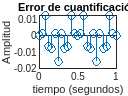

err=xnTs-xnq;
figure()
stem(nTs,err);
xlabel('tiempo (segundos)')
ylabel('Amplitud')
title('Error de cuantificación')

Para entender la naturaleza del ruido (error) de cuantificación se calculan algunas variables estadśiticas como la media y la desviación estandar. De acuerdo con la naturaleza de la señal y las condiciones del proceso de cuantificación, los valores de estas variables se pueden ver afectados

media_err=mean(err)

media_err = -0.0014

desv_err=std(err)

desv_err = 0.0079